# Add a Preprocessing Function

Instructions are in the task pane to the left. Complete and submit each task one at a time.

You can add a custom function **at the end** of your script. For data preprocessing, the function should take the data returned from the datastore as input. It should return the transformed data as output.

`function` `dataout` `=` `functionName``(``datain``)`

    `% do something with datain`

    `dataout` `=` `...`

`end`

Currently, you still need to call your function manually. To automate your data importing and preprocessing, you want your datastore to apply this function whenever the data is read. You can do this with a *transformed datastore*. The `transform` function takes a datastore and a function as inputs. It returns a new datastore as output. This transformed datastore applies the given function whenever it imports data.

Do not edit. This code creates a datastore, imports data, and visualizes it.

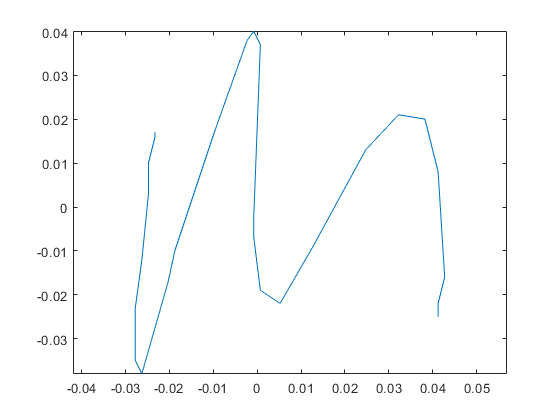

clear;clc
letterds = datastore("*_M_*.txt");
data = read(letterds);
data = scale(data);
plot(data.X,data.Y)
axis equal

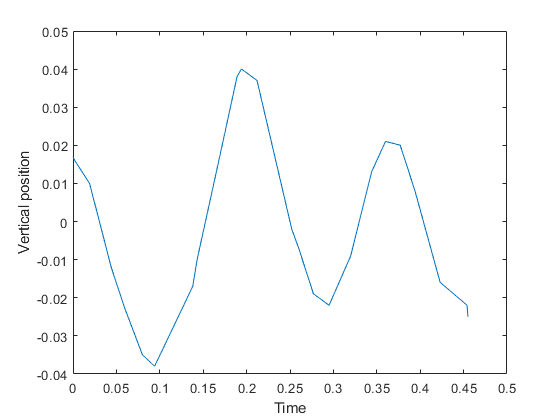

plot(data.Time,data.Y)
ylabel("Vertical position")
xlabel("Time")

To use a function as an input to another function, create a *function handle* by adding the `@` symbol to the beginning of the function name.

`transform``(``ds``,@``myfun``)`

A function handle is a reference to a function. Without the `@` symbol, MATLAB will interpret the function name as a call to that function.

## Task 2

Use the `transform` function to create a transformed datastore called `preprocds`. This datastore should apply the `scale` function to the data referenced by `letterds`.

preprocds = transform(letterds,@scale)

preprocds =   TransformedDatastore with properties:

    UnderlyingDatastore: [1×1 matlab.io.datastore.TabularTextDatastore]
             Transforms: {@scale}
            IncludeInfo: 0


The `scale` function should now be applied automatically whenever data is read from the `preprocds` datastore.

## Task 3

Use the `readall` function to import all the data. Check that the preprocessing function was applied to each file by plotting the `Y` variable as a function of `Time`.

dataall = readall(preprocds)

dataall = 5774×4 table
    Time          X             Y          P  
    _____    ___________    _________    _____

        0      -0.023278     0.017037    0.042
    0.002      -0.023278     0.016037    0.255
    0.002      -0.023278     0.016037    0.255
    0.019      -0.024778     0.010037     0.44
    0.027      -0.024778     0.003037    0.569
    0.044      -0.026278    -0.011963    0.745
     0.06      -0.027778    -0.022963      0.8
     0.08      -0.027778    -0.034963    0.851
    0.094      -0.026278    -0.037963     0.88
    0.138      -0.020278    -0.016963    0.894
    0.143      -0.018778    -0.009963    0.896
    0.169     -0.0097778     0.017037    0.899
    0.189     -0.0022778     0.038037    0.923
    0.194    -0.00077778     0.040037    0.931
    0.212     0.00072222     0.037037    0.995
    0.252    -0.00077778    -0.001963    

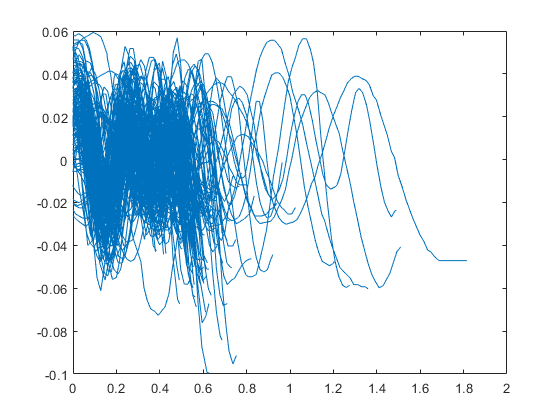

plot(dataall.Time,dataall.Y)

## Further Practice

Try visualizing the letters (`Y` against `X`) to ensure that they are centered on the origin. Check that the code works for the letter V without any modification.

Note that the size of the letters shouldn't matter to their classification. Different people have different sized writing. Can you add more preprocessing to scale the letters to a consistent size (without changing their shape)?

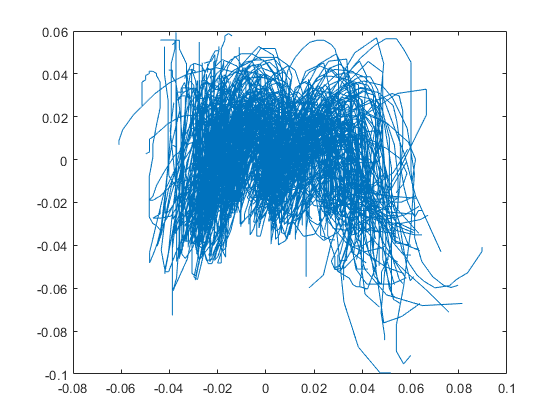

plot(dataall.X,dataall.Y)

## Tasks 1, 4, & 5

Create a function called `scale` at the end of the script that performs the following operations:

`data.Time` `=` `(``data.Time` `-` `data.Time``(``1``))``/``1000``;`

`data.X` `=` `1.5``*``data.X``;`

Because these commands modify the variable `data` directly, your function should use `data` as both the input and output variable.

Note that the third line of the script calls the `scale` function. Your script won't run until this function has been created.

Also note that local functions must be at the end of a script. This means you will be editing the script sections out of order in this interaction. The section headings show which section of the script to edit in each task.

**Tasks  4**

The location of a letter is not important for classifying it. What matters is the shape. A common preprocessing step for many machine learning problems is to normalize the data.

Typical normalizations include shifting by the mean (so that the mean of the shifted data is 0) or shifting and scaling the data into a fixed range (such as [-1, 1]). In the case of the handwritten letters, shifting both the x and y data to have 0 mean will ensure that all the letters are centered around the same point.

Modify the `scale` function to subtract the mean position from both components:

`data.X` `=` `data.X` `-` `mean``(``data.X``)``;`

`data.Y` `=` `data.Y` `-` `mean``(``data.Y``)``;`

Note that this will introduce a problem that will make the plot appear blank. You will fix this in the next task.

**Tasks  5**

Any calculations (including the default use of functions such as `mean`) involving `NaN`s will result in `NaN`. This is important in machine learning, where you often have missing values in your data. In the handwriting data, a `NaN` occurs wherever the writer lifted the pen from the tablet.

You can use the `"omitnan"` option to have statistical functions like `mean` ignore missing values.

`mean``(``x``,``"omitnan"``)`

function data = scale(data)
    data.Time = (data.Time - data.Time(1))/1000;
    data.X = 1.5*data.X;
    data.X = data.X-mean(data.X,"omitnan");
    data.Y = data.Y-mean(data.Y,"omitnan");
end